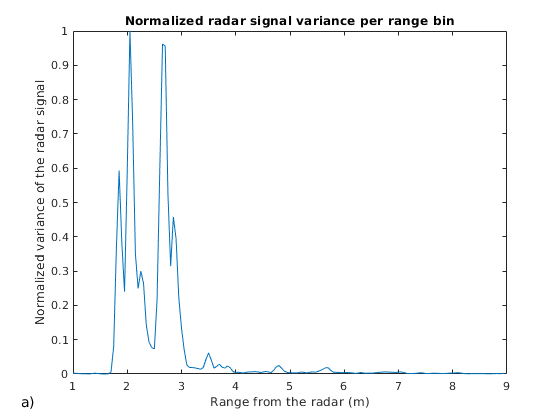

% Radar signal is read from the radar data. 
% There are two subjects - one about the range bin 41 and another around
% the range bin 54.
% We will plot only the data from the first closer subject
load('radar_sig.mat')
%plot variance per range bin
% select the highest variance greater than 20 range bins
fs=17;
t=1/17:1/17:length(radar_sig(:,40))/17;
figure
range_bin=20:179;
var_per_bin=var(radar_sig(:,range_bin));
plot(range_bin*0.05, rescale1(var_per_bin'))
xlabel('Range from the radar (m)')
ylabel('Normalized variance of the radar signal')
title('Normalized radar signal variance per range bin')
annonation_save('a)',"Fig11.6a.jpg", 1);


[m,i]=max(var(radar_sig(:,21:end)));
max_var=20+i;
% The subject is at the distance in cm:
disp(['Distance from the subject:' int2str(floor(max_var*5.3)) 'cm'])

Distance from the subject:217cm


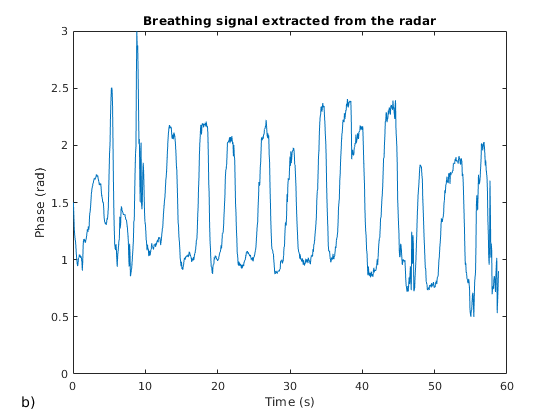

figure
plot(t(1:1000),unwrap(phase(radar_sig(1:1000,max_var))))
xlabel('Time (s)')
ylabel('Phase (rad)')
title('Breathing signal extracted from the radar')
annonation_save('b)',"Fig11.6b.jpg", 1);